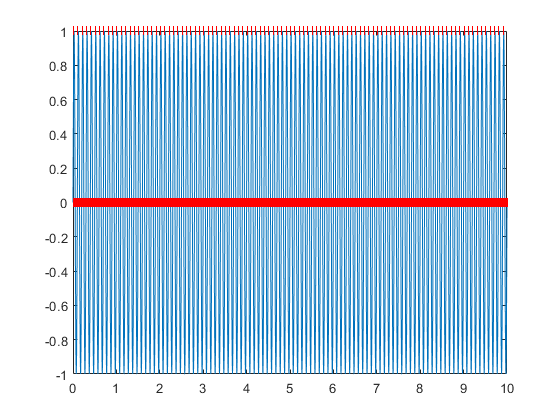

fs = 1e4;
t = 0:1/fs:10;
X = sin(2*pi*10*t);
raster = zeros(1,length(t));

for i=2:length(t)-1
    if (X(i-1)<=0.75 && X(i)>=0.75 && X(i+1)>0.75)
        raster(i) = 1;
    end
end

figure;
plot(t,X,t,raster,'r|');

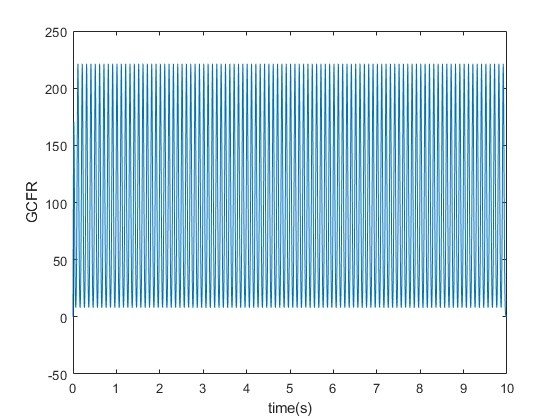






L = 1000; %5000
alpha =4;%8;
gauss_win = gausswin(L, alpha);
% gauss_win_norm = gauss_win.*(fs/L);
% wvtool(gauss_win_norm);
% gcfr =filter(gauss_win,1,raster).*(fs/L);
gcfr = filtfilt(gauss_win, 1, raster);
% gcfr = conv(raster, gauss_win, "same").*(fs/L) ;

figure;
plot(t, gcfr);
xlabel('time(s)');
ylabel('GCFR');

% title('L=0.1 s, alpha =4');

% N = 1000;
% n = -(N-1)/2:(N-1)/2;
% alpha = 4;
% 
% stdev = (N-1)/(2*alpha);
% y = (exp(-1/2*(n/stdev).^2)).*(fs/L);     
% plot(n,y);
% 
% gcfr = filtfilt(y,1,raster);
% plot(t,gcfr);
